# **Week2 - Optical Channel with BPSK**

The code below implements a preliminary model of an optical channel without DSPs and aims to investigate the feasibility of the model and the variation of the bit error rate (BER) with the signal-to-noise ratio (SNR)

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Modulation

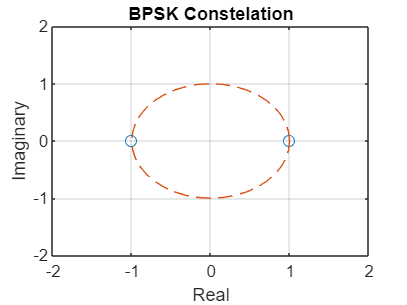

clear all; clearvars;

% Modulation parameters
M = 2; % Modulation order
k = log2(M); % Bits per symbol

% Visualising constellation
alphabet = 0:M-1;
symbols = pskmod(alphabet, M);
plot(real(symbols), imag(symbols), "o");
title("BPSK Constelation");
xlabel("Real");
ylabel("Imaginary");
grid on;
hold on;
phase = [0:pi/20:2*pi];
circleX = cos(phase); circleY = sin(phase);
plot(circleX, circleY, "--");
xlim([-2,2]); ylim([-2,2])
hold off


% Generating random bit sequence(s)
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
NSequences = 20; % No. of bit sequences

sourceBits = randi([0 1], NSymb*k, NSequences); % Matrix of source bits
sourceSymbols = pskmod(sourceBits, M) % Maps source bit vector to symbol vector

sourceSymbols =   -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i
  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0

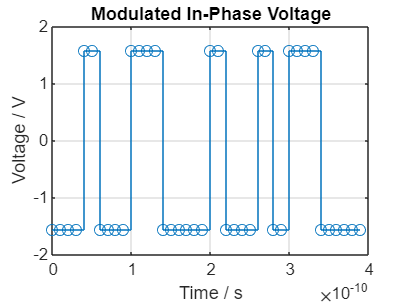


% bpskmod mapping: 0 -> 1+0i and 1 -> -1+0i

T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% Modulating voltage with generated symbols
DCOffset = 0; % DC offset of modulated current in V
Vmax = 1; % Sets the maximum value of the voltage
voltageLevels = [-pi/2, pi/2]';
realVals = [1 -1]'; % Storing the unique real values in the symbol constellation

vI = ones(size(sourceSymbols));
vQ = ones(size(sourceSymbols))*pi/2; % Quadrature voltage not significant as all symbols in BPSK have same imag. component

% Mapping the distinct real & imaginary values to their respective voltage levels
vI(real(sourceSymbols)>0) = voltageLevels(2); % Maps 1 -> pi
vI(real(sourceSymbols)<0) = voltageLevels(1); % Maps -1 -> 0
vIupsampled = repelem(vI, SpS, 1); % Upsampling the voltage waveform based on SpS

vQupsampled = repelem(vQ, SpS, 1); % Upsampling the voltage waveform based on SpS

% testVI = zeros(NSymb*SpS, 1); testVQ = testVI; % Test voltages which do not modulate the amplitude

% Visualising in-phase and quadrature voltages
stairs(t(1:20*SpS), vIupsampled(1:20*SpS,1), "o-");
title("Modulated In-Phase Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

### Pulse Shaping

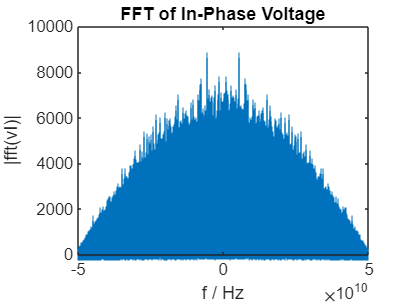

% Frequency spectrum of voltage waveform before filtering
fft_vI = fftshift(fft(vIupsampled(:,11)));
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);
stem(freqArr, abs(fft_vI), "|");
title("FFT of In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(vI)|");

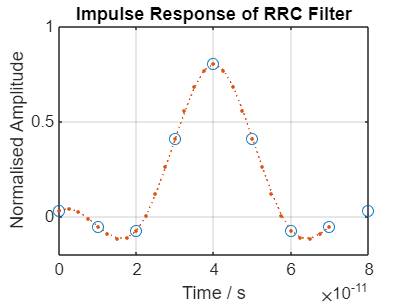


% Visualisation of RRC filter
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
filterResponse_t_interp = [0:0.25:filterSpan*SpS - 1]*T;
filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

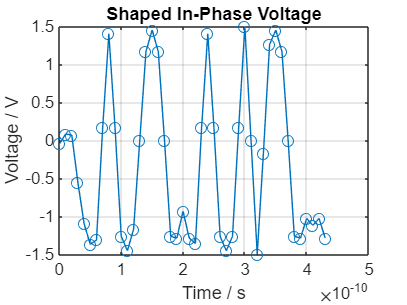


% Using RC filter to shape vI and vQ
shapedVI = upfirdn(vI, filterResponse, SpS, 1);
shapedVQ = upfirdn(vQ, filterResponse, SpS, 1);

% Visualising pulse-shaped voltages
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
shapedVI_t = [0:1:samples-1]*T;
plot(shapedVI_t(1:20*SpS + filterSpan), shapedVI(1:20*SpS + filterSpan,1), "o-");
title("Shaped In-Phase Voltage")
ylabel("Voltage / V")
xlabel('Time / s');
grid on

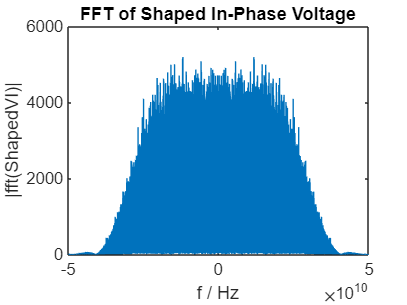


% Frequency spectrum of voltage waveform after filtering
fft_shapedVI = fftshift(fft(shapedVI(:,1)));
freqArr = [-samples/2:samples/2 - 1]/(T*samples);
plot(freqArr, abs(fft_shapedVI));
title("FFT of Shaped In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(ShapedVI)|");
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10


% Eye diagram of voltage waveform before filtering
% eyediagram(vI(1:1000,1), SpS);
% title("Eye Diagram of Discrete In-Phase Voltage")
% eyediagram(shapedVI(1:1000,1), SpS);
% title("Eye Diagram of Pulse-Shaped In-Phase Voltage")

### IQ Modulation

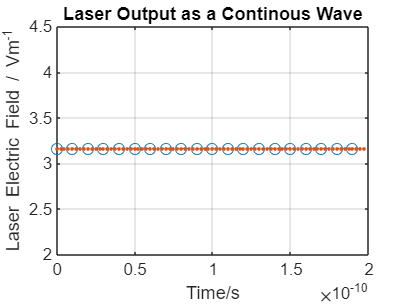

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 40;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
t_interp = [0:0.25:NSymb*SpS - 1]*T;
E_interp = interp1(t, real(laserE), t_interp, "spline");
plot(t(1:20), real(laserE(1:20)), "o", t_interp(1:80), E_interp(1:80),":.");
title("Laser Output as a Continous Wave")
xlabel("Time/s")
ylabel("Laser Electric Field / Vm^{-1}")
grid on

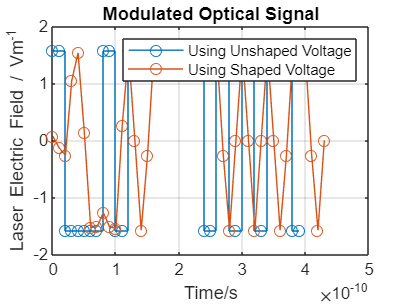


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi
modOpticSig = IQModulatorModified(vIupsampled, vQupsampled, laserE, Vpi);
modOpticSig_shaped = IQModulatorModified(shapedVI, shapedVQ, laserE_shaped, Vpi);

% Visualising modulated optic signal
stairs(t(1:20*SpS), real(modOpticSig(1:20*SpS,11)), "o-");
hold on
plot(t(1:20*SpS+ filterSpan), real(modOpticSig_shaped(1:20*SpS+ filterSpan, 11)), "o-");
title("Modulated Optical Signal")
xlabel("Time/s")
ylabel("Laser Electric Field / Vm^{-1}")
legend("Using Unshaped Voltage", "Using Shaped Voltage")
grid on
hold off

## Optical Channel

### Adding AWGN

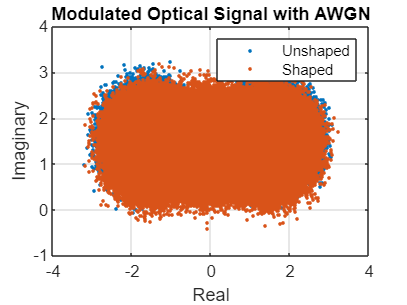

% Adding AWGN to laser output
laserEMag = sqrt(laserPw_Lin);
modLaserSymbs = laserEMag*0.5*sin(0.5*[-pi/2, pi/2]*pi/Vpi); % Symbol values in the modulated laser output
powerPerSymb = mean(modLaserSymbs.^2);
powerPerBit = powerPerSymb/k;

powerPerSymb_shaped = mean(real(modOpticSig_shaped).^2, "all");
powerPerBit_shaped = powerPerSymb_shaped/k;

SNRb_dB = [0:NSequences-1]'; % SNR per bit in dB

for i=1:NSequences
    SNRb_Lin(i,1) = 10^(SNRb_dB(i,1)/10); % linear SNR per symbol
    AWGN_StdDev(i,1) = sqrt(powerPerBit/SNRb_Lin(i,1)); % AWGN Standard deviation (no shaping)
    modOpticSig_AWGN(:,i) = modOpticSig(:,i) + (1/sqrt(2))*AWGN_StdDev(i,1)*randn(size(modOpticSig, 1),1) + (1i/sqrt(2))*AWGN_StdDev(i,1)*randn(size(modOpticSig, 1),1); % Noisy laser output
    % AWGN_StdDev_shaped(i,1) = sqrt(powerPerBit_shaped/SNRb_Lin(i,1)); % AWGN Standard deviation (shaping)
    % modOpticSig_shaped_AWGN(:,i) = modOpticSig_shaped(:,i) + (1/sqrt(2))*AWGN_StdDev_shaped(i,1)*randn(size(modOpticSig_shaped, 1),1) + (1i/sqrt(2))*AWGN_StdDev_shaped(i,1)*randn(size(modOpticSig_shaped, 1),1); % Noisy laser output
    modOpticSig_shaped_AWGN(:,i) =  awgn(modOpticSig_shaped(:,i), i, "measured");
end

plot(real(modOpticSig_AWGN(:,11)), imag(modOpticSig_AWGN(:,11)), ".");
hold on
plot(real(modOpticSig_shaped_AWGN(:,11)), imag(modOpticSig_shaped_AWGN(:,11)), ".");
title("Modulated Optical Signal with AWGN")
xlabel("Real")
ylabel("Imaginary")
legend("Unshaped", "Shaped")
grid on
hold off


% Checking model feasibility before introducing optical front-end
% Direct decoding of laser output
% filtered_symbols = upfirdn(real(modOpticSig_shaped_AWGN), filterResponse, 1, SpS);
% filtered_symbols = filtered_symbols(filterSpan + 1:end - filterSpan,:);
% tempDecodedBits = zeros(size(filtered_symbols));
% tempDecodedBits (real(filtered_symbols) <= 0) = 1;
% tempDecodedBits (real(filtered_symbols) > 0) = 0;
% 
% for i=1:NSequences
%     [numErrors(i,1), BER(i,1)] = biterr(tempDecodedBits(:,i) , sourceBits(:,i));
% end
% 
% semilogy(SNRb_dB, BER, 'o-')
% title("BER vs. SNR")
% ylabel("BER")
% xlabel("SNR per bit / dB")
% grid on



### Adding CD

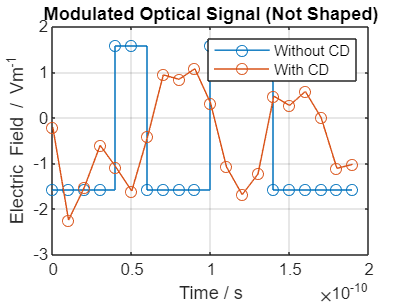

D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m
linkLength = 50e3; % Fibre link length in m

% eyediagram(real(modOpticSig(1:100,11)), SpS);

for i=1:NSequences
    modOpticSig_CD(:,i) = CDInsertion(modOpticSig(:,i), SpS, Rs, D, CLambda, linkLength, 1);
    modOpticSig_shaped_CD(:,i) = CDInsertion(modOpticSig_shaped(:,i), SpS, Rs, D, CLambda, linkLength, 1);
    modOpticSig_AWGN_CD(:,i) = CDInsertion(modOpticSig_AWGN(:,i), SpS, Rs, D, CLambda, linkLength, 1);
    modOpticSig_shaped_AWGN_CD(:,i) = CDInsertion(modOpticSig_shaped_AWGN(:,i), SpS, Rs, D, CLambda, linkLength, 1);
end

% Visualising optical signal before and after CD insertion:
% Without Pulse Shaping
stairs(t(1:10*SpS), real(modOpticSig(1:10*SpS,1)), "-o"); 
hold on
plot(t(1:10*SpS), real(modOpticSig_CD(1:10*SpS,1)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field / Vm^{-1}")
title("Modulated Optical Signal (Not Shaped)")
legend("Without CD", "With CD")
grid on
hold off

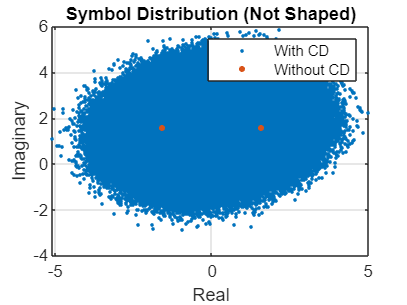


plot(real(modOpticSig_CD(:,1)), imag(modOpticSig_CD(:,1)), '.');
hold on
plot(real(modOpticSig(:,1)), imag(modOpticSig(:,1)), '.', "MarkerSize", 10);
xlabel("Real"); 
ylabel("Imaginary")
title("Symbol Distribution (Not Shaped)")
legend("With CD", "Without CD")
grid on
hold off

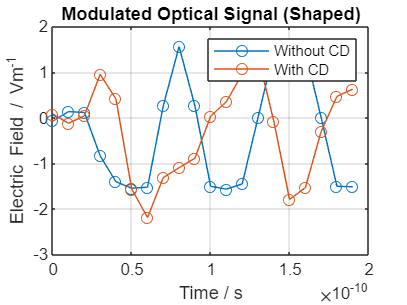

% -------------------------------------------------------------------------------

% With Pulse Shaping
plot(t(1:10*SpS), real(modOpticSig_shaped(1:10*SpS,1)), "-o"); 
hold on
plot(t(1:10*SpS), real(modOpticSig_shaped_CD(1:10*SpS,1)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field / Vm^{-1}")
title("Modulated Optical Signal (Shaped)")
legend("Without CD", "With CD")
grid on
hold off

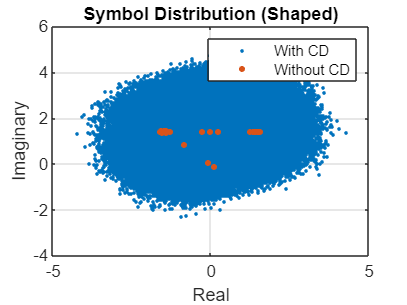


plot(real(modOpticSig_shaped_CD(:,1)), imag(modOpticSig_shaped_CD(:,1)), '.');
hold on
plot(real(modOpticSig_shaped(:,1)), imag(modOpticSig_shaped(:,1)), '.', "MarkerSize", 10);
xlabel("Real"); 
ylabel("Imaginary")
title("Symbol Distribution (Shaped)")
legend("With CD", "Without CD")
grid on
hold off


% Premature CD compensation to check model feasibility
% c = 299792458; % Speed of light
% N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)); % CD Equalizer Length
% Np = 2*ceil(sqrt((pi*c*T^2)^2 + (2*(D*10e-6)*linkLength*CLambda^2)^2)/(pi*c*T^2)) + 2;
% 
% for i=1:NSequences
%     modOpticSig_CDC(:,i) = OverlapSaveCDC(modOpticSig_CD(:,i), D, linkLength, CLambda, Rs, 1, SpS, 2e5, N_CD);
% end
% 
% % Visualising symbols after CD compensation
% plot(real(modOpticSig_CDC(:,1)), imag(modOpticSig_CDC(:,1)), '.');
% xlabel("Real"); 
% ylabel("Imaginary")
% title("Symbol Distribution after CD Compensation")
% grid on 


% eyediagram(real(modOpticSig(1:100,11)), SpS);

## Receiver

### Optical Front-End

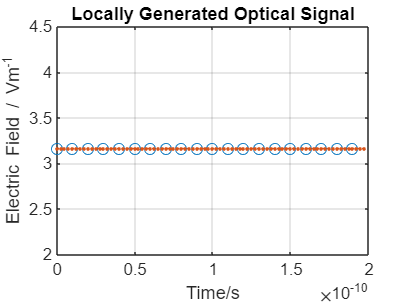

% Generating Local optical signal for coherent detection
Elo = laserE; % Identical to initial laser source
Elo_shaped = laserE_shaped;

% Visualising locally generated optical signal
Elo_interp = interp1(t, real(Elo), t_interp, "spline")';
plot(t(1:20), real(Elo(1:20,1)), "o", t_interp(1:80), Elo_interp(1:80,1),":.");
title("Locally Generated Optical Signal")
xlabel("Time/s")
ylabel("Electric Field / Vm^{-1}")
grid on

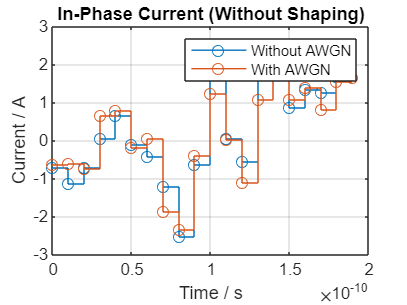


% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

count = 1;

for i=1:size(modOpticSig,2)
    % Output from Optical Front-End
    OpticFEOut(:,count:count+1) = OpticalFrontEnd(modOpticSig_CD(:,i), Elo, eta_ph, 1);
    OpticFEOut_AWGN(:,count:count+1) = OpticalFrontEnd(modOpticSig_AWGN_CD(:,i), Elo, eta_ph, 1);
    OpticFEOut_shaped(:,count:count+1) = OpticalFrontEnd(modOpticSig_shaped_CD(:,i), Elo_shaped, eta_ph, 1);
    OpticFEOut_shaped_AWGN(:,count:count+1) = OpticalFrontEnd(modOpticSig_shaped_AWGN_CD(:,i), Elo_shaped, eta_ph, 1);
    count = count+2;
end

stairs(t(1:10*SpS), OpticFEOut(1:10*SpS,21), "-o"); % In-phase current
hold on
stairs(t(1:10*SpS), OpticFEOut_AWGN(1:10*SpS,21), "-o")
title("In-Phase Current (Without Shaping)")
xlabel("Time / s")
ylabel("Current / A")
legend("Without AWGN", "With AWGN")
grid on
hold off

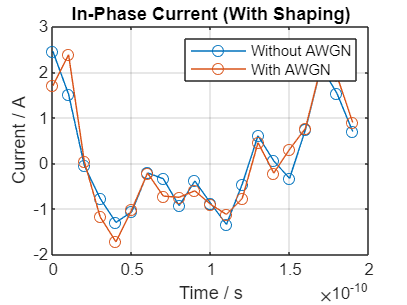


plot(t(1:10*SpS), OpticFEOut_shaped(1:10*SpS,21), "-o"); % In-phase current
hold on
plot(t(1:10*SpS), OpticFEOut_shaped_AWGN(1:10*SpS,21), "-o")
title("In-Phase Current (With Shaping)")
xlabel("Time / s")
ylabel("Current / A")
legend("Without AWGN", "With AWGN")
grid on
hold off


% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components
OpticalFEOut_I = TIA_Gain*OpticFEOut(1:end, 1:2:end); OpticalFEOut_I_AWGN = TIA_Gain*OpticFEOut_AWGN(1:end, 1:2:end);
OpticalFEOut_Q = TIA_Gain*OpticFEOut(1:end, 2:2:end); OpticalFEOut_Q_AWGN = TIA_Gain*OpticFEOut_AWGN(1:end, 2:2:end);
OpticalFEOut_I_shaped = TIA_Gain*OpticFEOut_shaped(:, 1:2:end); OpticalFEOut_I_shaped_AWGN = TIA_Gain*OpticFEOut_shaped_AWGN(:, 1:2:end);
OpticalFEOut_Q_shaped = TIA_Gain*OpticFEOut_shaped(:, 2:2:end); OpticalFEOut_Q_shaped_AWGN = TIA_Gain*OpticFEOut_shaped_AWGN(:, 2:2:end);


## DSP

### CD Compensation

% Scaling factor between output of IQM and output of optical front-end
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag/2;

% Cancelling the scaling factor:
% NOT Shaped
voltageI_scaled = OpticalFEOut_I/scaleFactor; voltageQ_scaled = OpticalFEOut_Q/scaleFactor; 
voltageI_AWGN_scaled = OpticalFEOut_I_AWGN/scaleFactor; voltageQ_AWGN_scaled = OpticalFEOut_Q_AWGN/scaleFactor; 
% Shaped
voltageI_shaped_scaled = OpticalFEOut_I_shaped/scaleFactor; voltageQ_shaped_scaled = OpticalFEOut_Q_shaped/scaleFactor; 
voltageI_shaped_AWGN_scaled = OpticalFEOut_I_shaped_AWGN/scaleFactor; voltageQ_shaped_AWGN_scaled = OpticalFEOut_Q_shaped_AWGN/scaleFactor; 


% CD Compensation
c = 299792458; % Speed of light
N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)); % CD Equalizer Length

for i=1:NSequences
    voltage_CDC(:,i) = OverlapSaveCDC(voltageI_scaled(:,i)+1i*voltageQ_scaled(:,i), D, linkLength, CLambda, Rs, 1, SpS, 2e5, N_CD);
    voltage_shaped_CDC(:,i) = OverlapSaveCDC(voltageI_shaped_scaled(:,i)+1i*voltageQ_shaped_scaled(:,i), D, linkLength, CLambda, Rs, 1, SpS, 2e5, N_CD);
    voltage_AWGN_CDC(:,i) = OverlapSaveCDC(voltageI_AWGN_scaled(:,i)+1i*voltageQ_AWGN_scaled(:,i), D, linkLength, CLambda, Rs, 1, SpS, 2e5, N_CD);
    voltage_shaped_AWGN_CDC(:,i) = OverlapSaveCDC(voltageI_shaped_AWGN_scaled(:,i)+1i*voltageQ_shaped_AWGN_scaled(:,i), D, linkLength, CLambda, Rs, 1, SpS, 2e5, N_CD);

end

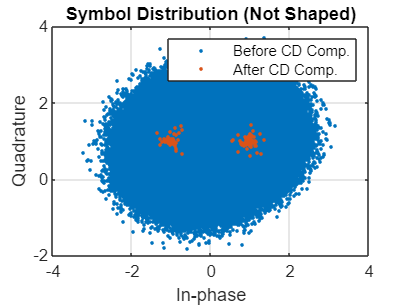


% Visualisation of symbols before and after CD compensation
plot(voltageI_scaled(:,1), voltageQ_scaled(:,1), '.')
hold on
plot(voltage_CDC(:,1), '.')
title("Symbol Distribution (Not Shaped)")
xlabel("In-phase")
ylabel("Quadrature")
legend("Before CD Comp.", "After CD Comp.")
grid on
hold off

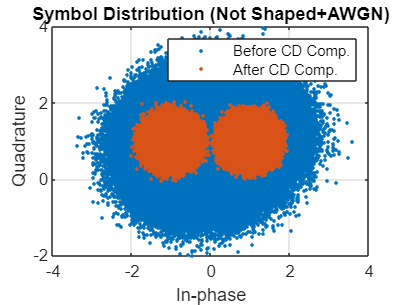


plot(voltageI_AWGN_scaled(:,11), voltageQ_AWGN_scaled(:,11), '.')
hold on
plot(voltage_AWGN_CDC(:,11), '.')
title("Symbol Distribution (Not Shaped+AWGN)")
xlabel("In-phase")
ylabel("Quadrature")
legend("Before CD Comp.", "After CD Comp.")
grid on
hold off

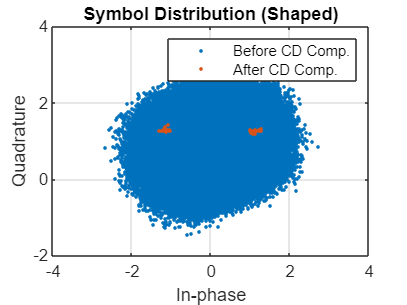


% Downsample unshaped signals after CD compensation
voltageI = real(voltage_CDC(1:SpS:end, :)); voltageQ = imag(voltage_CDC(1:SpS:end, :));
voltageI_AWGN = real(voltage_AWGN_CDC(1:SpS:end, :)); voltageQ_AWGN = imag(voltage_AWGN_CDC(1:SpS:end, :));

% Passing shaped components through matched filter and downsampling
voltageI_shaped = upfirdn(real(voltage_shaped_CDC), filterResponse, 1, SpS); voltageI_shaped = voltageI_shaped(filterSpan + 1:end - filterSpan,:);
voltageQ_shaped = upfirdn(imag(voltage_shaped_CDC), filterResponse, 1, SpS); voltageQ_shaped = voltageQ_shaped(filterSpan + 1:end - filterSpan,:);
voltageI_shaped_AWGN = upfirdn(real(voltage_shaped_AWGN_CDC), filterResponse, 1, SpS); voltageI_shaped_AWGN = voltageI_shaped_AWGN(filterSpan + 1:end - filterSpan,:);
voltageQ_shaped_AWGN = upfirdn(imag(voltage_shaped_AWGN_CDC), filterResponse, 1, SpS); voltageQ_shaped_AWGN = voltageQ_shaped_AWGN(filterSpan + 1:end - filterSpan,:);

plot(voltageI_shaped_scaled(:,1), voltageQ_shaped_scaled(:,1), '.')
hold on
plot(voltageI_shaped(:,1), voltageQ_shaped(:,1), '.')
title("Symbol Distribution (Shaped)")
xlabel("In-phase")
ylabel("Quadrature")
legend("Before CD Comp.", "After CD Comp.")
grid on
hold off

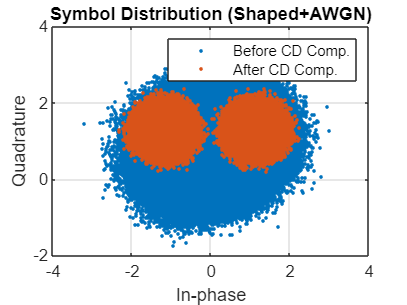


plot(voltageI_shaped_AWGN_scaled(:,11), voltageQ_shaped_AWGN_scaled(:,11), '.')
hold on
plot(voltageI_shaped_AWGN(:,11), voltageQ_shaped_AWGN(:,11), '.')
title("Symbol Distribution (Shaped+AWGN)")
xlabel("In-phase")
ylabel("Quadrature")
legend("Before CD Comp.", "After CD Comp.")
grid on
hold off

### Decision

% Mapping scaled voltages to inital in-phase component of the symbol
% constellation.
% Quadrature component is ignored as it is the same value for all symbols.
% Maximum likelihood estimation, based on the Euclidian distance between the recieved voltage points
% and those corresponding to the symbols, is used.
decodedSymbols = ones(size(voltageI)); 
decodedSymbols(voltageI > 0) = 1; decodedSymbols(voltageI <= 0) = -1;
decodedInts = pskdemod(decodedSymbols, M);
decodedBits = int2bit(decodedInts, k);
biterr(decodedBits, sourceBits)

ans = 0


decodedSymbols_AWGN = ones(size(voltageI_AWGN));
decodedSymbols_AWGN(voltageI_AWGN > 0) = 1; decodedSymbols_AWGN(voltageI_AWGN <= 0) = -1;
decodedInts_AWGN = pskdemod(decodedSymbols_AWGN, M);
decodedBits_AWGN = int2bit(decodedInts_AWGN, k);

decodedSymbols_shaped = ones(size(voltageI_shaped));
decodedSymbols_shaped(voltageI_shaped > 0) = 1; decodedSymbols_shaped(voltageI_shaped <= 0) = -1;
decodedInts_shaped= pskdemod(decodedSymbols_shaped, M);
decodedBits_shaped = int2bit(decodedInts_shaped, k);
biterr(decodedBits_shaped, sourceBits)

ans = 0

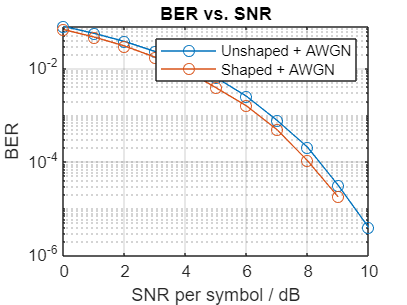


decodedSymbols_shaped_AWGN = ones(size(voltageI_shaped_AWGN));
decodedSymbols_shaped_AWGN(voltageI_shaped_AWGN > 0) = 1; decodedSymbols_shaped_AWGN(voltageI_shaped_AWGN <= 0) = -1;
decodedInts_shaped_AWGN= pskdemod(decodedSymbols_shaped_AWGN, M);
decodedBits_shaped_AWGN = int2bit(decodedInts_shaped_AWGN, k);

BER_BPSK_AWGN = zeros(NSequences,1); numErrors = zeros(NSequences,1);
BER_BPSK_AWGN_shaped = zeros(NSequences,1); numErrors_shaped = zeros(NSequences,1);

for i=1:NSequences
    [numErrors(i,1), BER_BPSK_AWGN(i,1)] = biterr(sourceBits(:,i), decodedBits_AWGN(:,i));
    [numErrors_shaped(i,1), BER_BPSK_AWGN_shaped(i,1)] = biterr(sourceBits(:,i), decodedBits_shaped_AWGN(:,i));
end

semilogy(SNRb_dB, BER_BPSK_AWGN, 'o-')
hold on
semilogy(SNRb_dB, BER_BPSK_AWGN_shaped, 'o-')
title("BER vs. SNR")
ylabel("BER")
xlabel("SNR per symbol / dB")
legend("Unshaped + AWGN", "Shaped + AWGN")
grid on
hold off


% save("BPSKData.mat","SNRb_dB", "BER_BPSK")